# Making an oscilloscope display

2 jan 23 B.R.

## Objective

The previous file, `matlabMeetsArduino.mlx`, concluded with an Arduino program, `oscope1.ino`. Here we'll develop Matlab code to interface with the Arduino and display time series data (voltage vs. time), like an oscilloscope. 

There are many ways we could interface with an Arduino running `oscope1.ino`, and I'll show you an evolution of features (and complexity). 

## Initialization 

As described in `matlabMeetsArduino.mlx`, we need to (somehow) find the name of the serial port corresponding to the Arduino. Comparing `serialportlist` befor and after plugging in/out the Arduino should reveal its name. On my computer (Macbook Pro), the Arduino is always the last one so I initialize by: 

Attempting this twice will result in an error, so we can force a single instance as follows: 

if ~exist('ard','var') % initalize arduino
    disp('initializing arduino ...')
    ports = serialportlist; ardPort = ports{end}; % works for me, substitute appropriate port for yours
    ard = serialport(ardPort,115200,'Timeout',2); 
    configureTerminator(ard, 0);
    clear ports ardPort; % clean up workspace
    pause(2); % time for Arduino to boot
end

## Simplest oscilloscope display

Our simplest interface is probably below:

writeline(ard, 'b');  % request data
bin = read(ard,804,'int16');
data = reshape(bin(1:800),2,400)' - 1; 
plot(data); xlabel('sample #'); ylabel('ADU')

We request a buffer of data from Arduino by sending it the ASCII letter '`b`' with `writeline`. Sample number isn't the most standard unit of time, so let's use the measured elapsed time to recalibrate the time axis: 

dt = bitshift(bin(802),16) + bin(801); % microseconds
t = linspace(0,dt/1000,400)'; % time vector
plot(t, data, '.-'); xlabel('time/msec'); ylabel('voltage/ADU')

That draws one trace, much as an oscilloscope does in "single sweep" mode. How to automatically sweep or "retrigger"? Simplest is to copy it (to a script file, e.g., `oscope1.m`) inside a `while true ... end` construct, so it loops until you enter Control-C (or Command-C depending on your computer). A problem is that Control-C sends a "signal" to stop the executing code *immediately* and that can leave the serial port object in an undetermined state, like with a partial buffer. 

## Adding a run button

Matlab can add a graphical user interface (GUI) button with a single command, (`doc` `uicontrol)`. Trial and error and graphical tools help get parameters right, here's what I came up with: 

runBtn = uicontrol('style','radiobutton','string','run','units', ...
    'normalized','position',[.13 .93 .1 .04],'Callback','oscope1');

If you want to move it around, simply execute runBtn.Position = [...]; where because we've specified 'normalized' units, the botttom left corner of the figure window is at [0 0], the top right has coordinates [1 1], and the 4 Position components specify location and size. '`Callback`' specifies an action when the button is pressed, in this case to run a file called `oscope1`. I suggest you type `>> which oscope1` to make sure `path` is finding the file you expect. We should automate initialization of runBtn like we did Arduino. The uicontrol is a "child" of the figure window, so closing the figure deletes its children, but not it's name in the Workspace. So we'll need to create runBtn if it doesn't exist or if it is no longer valid, as below:

%% script oscope1.m -- display A0, A1 from an Arduino running oscope1.ino
if ~exist('runBtn','var') || ~isvalid(runBtn) % add the button once
    runBtn = uicontrol('style','radiobutton','string','run','units', ...
        'normalized','position',[.13 .93 .1 .04],'Callback', 'oscope1');
end

while runBtn.Value 
    writeline(ard,'b'); 
    bin = read(ard,804,'int16');
    data = reshape(bin(1:800),2,400)' - 1;
    dt = bitshift(bin(802),16)+bin(801); % microseconds
    t = linspace(0,dt/1000,400)';
    plot(t, data, '.-'); grid;
    xlabel('time/msec'); ylabel('voltage/ADU')
end

## Adding runOnce

Oscope1 only runs when someone presses the run button, but sometimes we'll want to automate it. A simple way is to add a Boolean variable that tells it to run once, why not call it `runOnce`: 

%% script oscope1.m -- first version of an Arduino oscilloscope display
% 3jan23 BR, Arduino running oscope1.ino, command set = b and p

if ~exist('runBtn','var') || ~isvalid(runBtn) % add the button once
    runBtn = uicontrol('style','radiobutton','string','run','units', ...
        'normalized','position',[.13 .93 .1 .04],'Callback', 'oscope1');
end
if ~exist('ard','var') % initalize arduino
    disp('initializing arduino ...')
    ports = serialportlist; ardPort = ports{end}; % works for me, substitute appropriate port for yours
    ard = serialport(ardPort,115200,'Timeout',2); 
    configureTerminator(ard, 0);
    clear ports ardPort; % clean up workspace
    pause(2); % time for Arduino to boot
end
if ~exist('runOnce','var'), runOnce = true; end

while runBtn.Value || runOnce
    writeline(ard,'b'); 
    bin = read(ard,804,'int16');
    data = reshape(bin(1:800),2,400)' - 1;
    dt = bitshift(bin(802),16)+bin(801); % microseconds
    t = linspace(0,dt/1000,400)';
    plot(t, data, '.-'); grid;
    xlabel('time/msec'); ylabel('voltage/ADU')
    runOnce = false;
end

Tthe `while` loop now executes when the run button is on or from the command line, `>> runOnce = true; oscope1;` produces new values of `bin, data, dt`, a new plot, and it only runs once because of the last line in the loop. Try it and make sure it works. 

## Adding a frame counter

I'm interested in speed!!! How many updates or frames per second are we getting? When I was writing and optimizing code for my microscope company (Etaluma.com) I wrote this simple function to display the frame rate, and with a tweak of where the result is displayed, it works perfectly here. It's always great when you can reuse code ... Add `displayfps;`, in the while loop and save this function in your PATH, i.e., in 310MatlabFiles folder: 

Some key lessons from this code: 

- It's a function, meaning its variables exist in a different workspace and variables such as` ard, runBtn, data`, ... aren't accessible. 

- `frame, ttime`, and `lblFPS` are `persistent` variables, meaning their values persist between successive calls to `displayfps`. By default, variables within functions disappear and are initialized in each function call.

- A `uicontrol` of style '`Text`' is created and updated -- same kind of object as our `runBtn`. 

- Every call to `displayfps` increments `frame = frame + 1;` and that's typically all it does, except every 5th frame, the frame rate is computed, the uicontrol's `String` field is updated, and the timer and frame counter are reset.

- It doesn't return any value. How would you refactor `displayfps` to return `fps` instead of just displaying it? Here's an alternative, that extracts fps from the graphics environment (not the function): `>> fps = sscanf(get(findobj('Tag','FPS'),'String'),'%f')` Let's unpack that. `findobj` returns "handles" to objects matching its arguements. We initialized the uicontrol with a (unique) '`Tag`' of value '`FPS`' making its handle easy to find. `get` returns a specified field from an object, in  this case the displayed string, e.g., '4.2 FPS', and `sscanf` parses the number (`'%f'`) from that string. Hope you further appreciate the power of Matlab ... 

## Adding error handling (try/catch)

Sometimes the following Warning and Error arise, apparently from some fault in the serial interface:

Turning off and on the runBtn usually fixes it, although flushing the serial buffer is a good idea to clear partial data: `>> flush(ard); `We can automate such error recovery with a `try/catch` construct. This revision 

## Speeding up the frame rate with graphics objects

## oscope1.m

Involke it the first time with: 

`>> oscope1`

which creates a `runBtn` object that calls the script, and places it in the top left of the current figure window. Next it connects to the Arduino and sets the Terminator character to 0. 

On MacOS, Arduino ports are named something like '`/dev/tty.usbserial-14310'.` Again its probably best to plug and unplug to verify the Arduino is called what you think it is. It turns out on my Macbook Pro that the Arduino is always the last item on the list, so I use that trick. You might use `strfind` or some other algorithm if you prefer.  If you think this is hokey, I agree. USB was described in its early days as "polishing a turd" ([https://m.eet.com/media/1139639/85406.pdf](https://m.eet.com/media/1139639/85406.pdf)). The cost to the economy of this messed up interface is enormous. Note that once we connect to the Arduino, it won't show up as available, so we can only connect once. If you unplug the Arduino, then `clear ard` will rerun this code. 

Finally, it creates a boolean `runOnce` variable (=`true`), so the while block runs once (the last line sets `runOnce = false;`). 

%% script oscope1.m -- a simple Arduino oscilloscope display
% 16oct22 BR, Arduino running oscope1, command set = b, p, s
if ~exist('runBtn','var') % add the button once
    runBtn = uicontrol('style','radiobutton','string','run','units', ...
        'normalized','position',[.13 .93 .1 .04]);
    runBtn.Callback = 'oscope1';
end
if ~exist('ard','var') % initalize arduino
    disp('initializing arduino ...')
    ports = serialportlist;
    ard = serialport(ports{end},115200);
    ard.Timeout = 2;
    configureTerminator(ard, 0);
    clear ports;
    pause(2); % time to boot
end
if ~exist('runOnce','var')
    runOnce = true;
end

while runBtn.Value || runOnce
    writeline(ard,'b'); 
    try
        bin = read(ard,804,'int16');
        dt = bitshift(bin(802),16)+bin(801); % microseconds
        data = reshape(bin(1:800),2,400)' - 1;
        t = linspace(0,dt/1000,400)'; % calibrate the time axis
    catch
        flush(ard);
        break;
    end
    try   % change data inside the plot is faster
        set(plotHandle(1),'XData',t,'YData',data(:,1));
        set(plotHandle(2),'XData',t,'YData',data(:,2));
    catch
        plotHandle = plot(t, data, '.-');
        xlabel('msec'); ylabel('ADU')
        legend('A0','A1'); grid on;
    end
    displayfps;
    drawnow;
    runOnce = false;
end

The while loop runs as long as the `runBtn` is checked or `runOnce` is `true`. First item is writing a "`b`" to Arduino, telling it to `measureWaveformsBinary();`. Next it tries to read 804` int16` numbers. The 801st and 802nd number are combined into a 32 bit elapsed time (in microseconds), and the first 1:800 numbers are reshaped into 2 columns of 400 samples of [A0 A1]. From `dt`, we compute a calibrated time vector `t`. If any error occured (e.g., 804 `int16`'s weren't read), we `flush(ard)` and run the `while` loop again. The next task is to `plot` the data. Here I use the `try/catch` construct in a tricky way to speed up the plotting. The first time, the `set(...)` command will fail (because `plotHandle` hasn't been created yet), so execution jumps to `catch`, `plotHandle` is created by `plot` and labels and legends are added. Subsequent times through the `while` loop, the two lines in the `try` block will succeed. They just change the `XData` and `YData` of the plots to the new data. That can save many milliseconds over calling `plot` each time. `displayfps` is a function (recycled from another application) that displays the frame rate in the bottom left corner, it's code is below. 

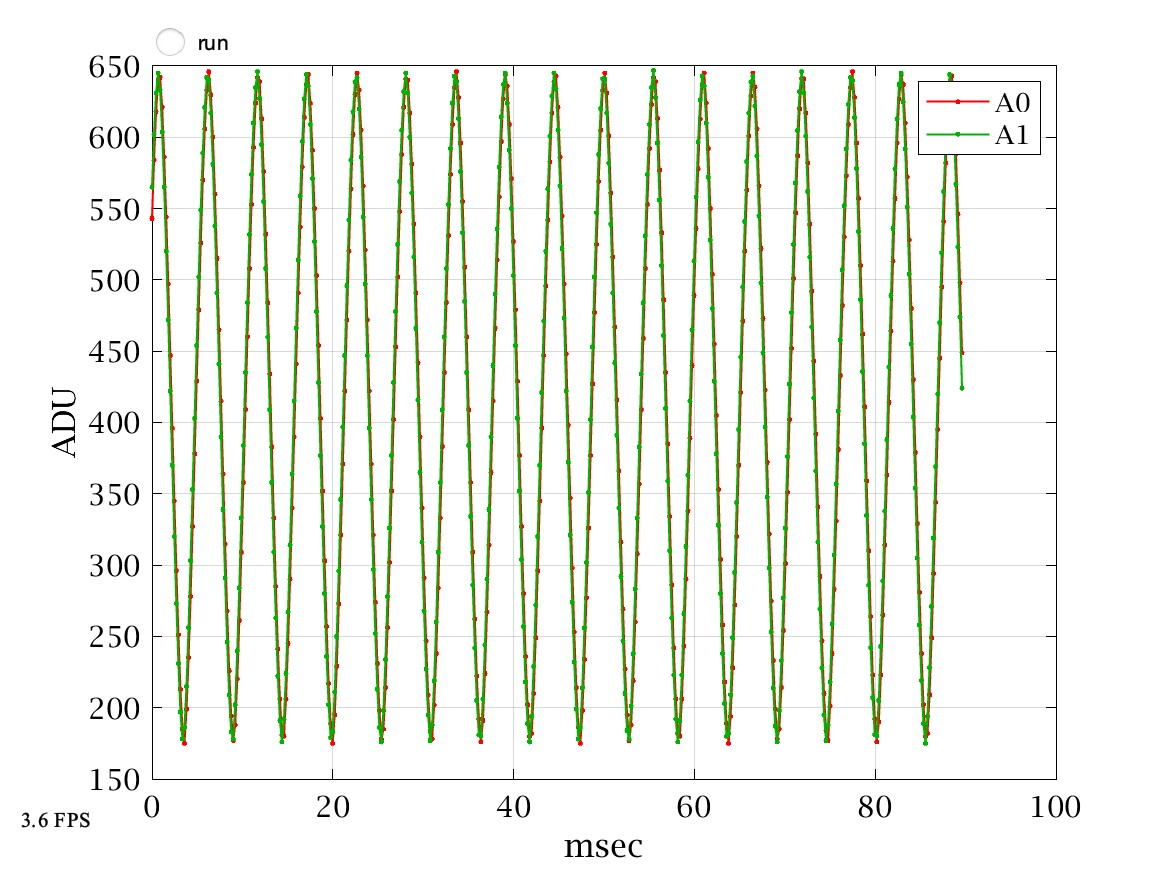

        oscope1.m display, with A0 and A1 connected (in parallel) to a function generator output at 183Hz. 

### Future Embellishments

There are lots of improvements to the interface and data processing. Some key ones that we'll tackle next are: 

- **Triggering**. The initial phase of a periodic signal is arbitrary, because the Arduino starts collecting data whenever it receives the "b" command, which is generally asynchronous with a signal. One solution might be to program the Arduino to wait for a threshold crossing (wait how long? That's called the "hold-off time" on an oscilloscope). But generally it's* easier* (not faster) to do this in Matlab. 

- **Interchannel deskewing**. Notice A0 and A1 data points are offset from each other, because the Arduino has a single analog-to-digital converter (ADC) that alternates sampling between A0 and A1. If we want to compare two waveforms *as if* they were measured simultaneously, then we have to fix this *systematic error*. It turns out that it's very easy to do, and we'll do it in both the time and frequency domains. 

- **Compute and display amplitudes and frequency**. Why not use the `title()` for useful information. Also calibrate the vertical scale --> volts. 

- **Spectrum analysis**. Sometimes its useful to display data in the frequency domain instead of the above "time domain". 

- What else is on your wish list? 

Each of these will be done with surprisingly few additional lines of Matlab code. 

## Conclusions

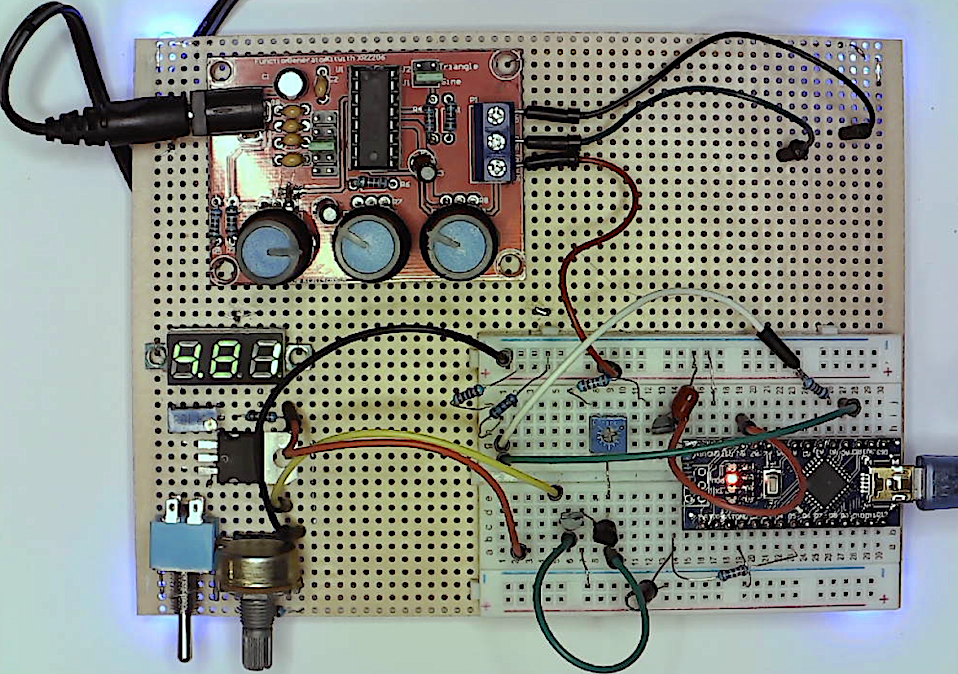

I started this project when Covid19 shut down in-person classes. I didn't want to give up the electronics lab and turn the class into pure circuit analysis theory. It was easy to conceive kits with an affordable variable DC power supply (LM317), a function generator (XR2206 kit), soldering kit and DMM. But an oscilloscope to visualize AC signals was out of budget. A $5 Arduino and Matlab have exceeded my expectations. (The same code runs on a $4 Raspberry pi Pico measuring ~70ksamples/second and displays >20 frames/second.) We started using the Arduino first to automate DC measurements, then automated LM317 voltage control and measurements, and now visualize (and soon quantify) AC measurements. Finally, we'll be automating Bode plots, with Arduino setting the function generator frequency, and Matlab computing AC amplitudes, frequencies, and phases. But all these years, there's been an intermittent unreliability that I didn't understand until today. Intermittent problems are generally hardest to troubleshoot. This code failed whenever analogread returned a value of 10 ... any other value worked fine. When a random length buffer was read, I didn't think of looking at the last value ... Now we know. 

What are your biggest epiphanies from this long activity?? 

## Appendix

### oscope1.ino